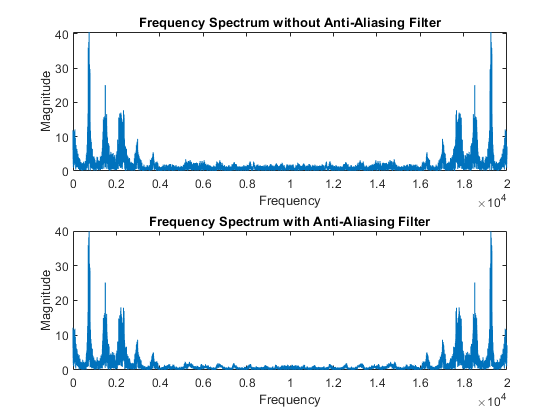

% Load the input audio file
[input, Fs] = audioread('MusaZaheer_BSCE21037.wav');

% Downsample the audio signal without anti-aliasing filter
factor = 2; % Downsampling factor
output_no_filter = input(1:factor:end);

% Apply anti-aliasing filter and downsample the input audio
f_cutoff = Fs/(2*factor); % Cutoff frequency in Hz
n_order = 22; % slope 
[b, a] = butter(n_order, f_cutoff/(Fs/2), 'low');%
input_filtered = filter(b, a, input);
output_with_filter = input_filtered(1:factor:end);

% Write output files
audiowrite('output_no_filter.wav', output_no_filter, Fs/factor);
audiowrite('output_with_filter.wav', output_with_filter, Fs/factor);

% Compute the frequency spectra of the output files
fft_output_no_filter = abs(fft(output_no_filter));
fft_output_with_filter = abs(fft(output_with_filter));
sound(output_no_filter, Fs/factor);
%sound(output_with_filter, Fs/factor);
% Plot the frequency spectra
figure;
subplot(2,1,1);
plot(fft_output_no_filter);
title('Frequency Spectrum without Anti-Aliasing Filter');
xlabel('Frequency');
ylabel('Magnitude');
subplot(2,1,2);
plot(fft_output_with_filter);
title('Frequency Spectrum with Anti-Aliasing Filter');
xlabel('Frequency');
ylabel('Magnitude');